# Polar Lines and Walls

## Question 6

load scan1

## Part A

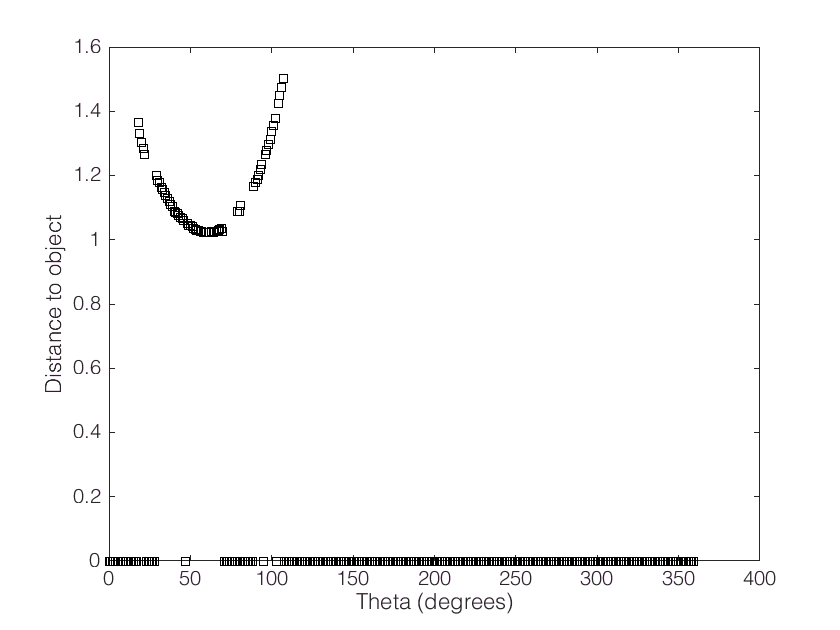

plot(theta,r,'ks'); xlabel('Theta (degrees)'); ylabel('Distance to object');

## Part B

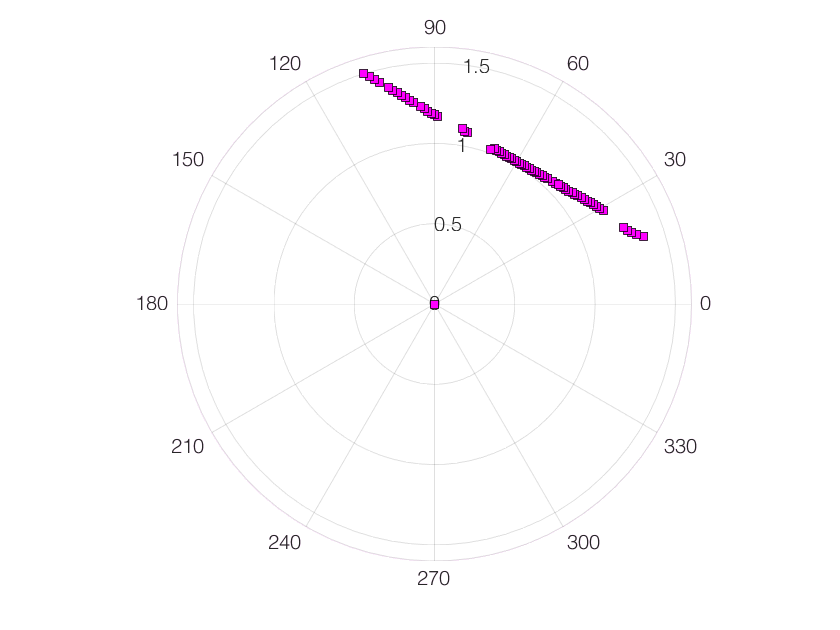

polarplot(deg2rad(theta),r,'ks', 'MarkerSize', 6, 'MarkerFaceColor', 'm');

## Part D

theta_clean = theta(r~=0);
r_clean = r(r~=0);

## Part E

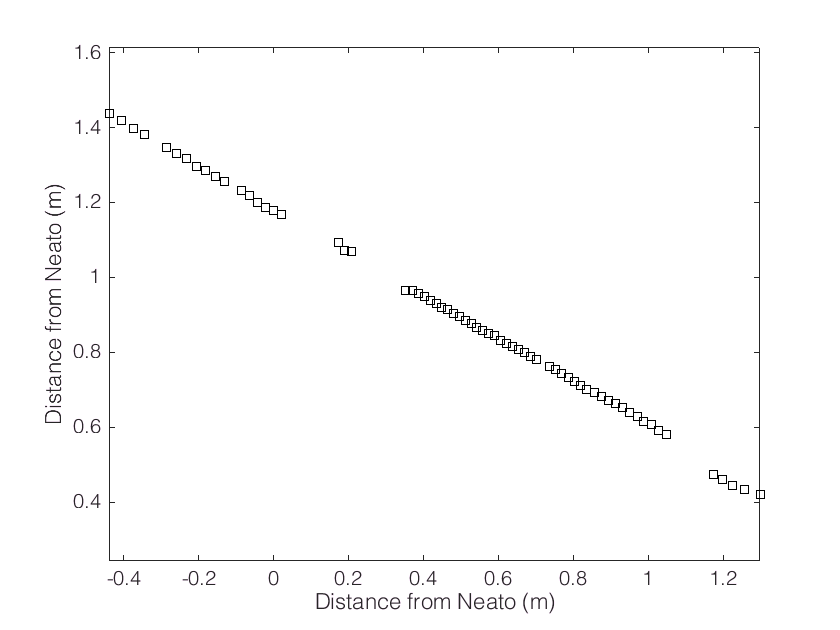

x = r_clean.*cosd(theta_clean);
y = r_clean.*sind(theta_clean);
plot(x, y, 'ks'); xlabel('Distance from Neato (m)'); ylabel('Distance from Neato (m)'); axis equal;

## Question 7

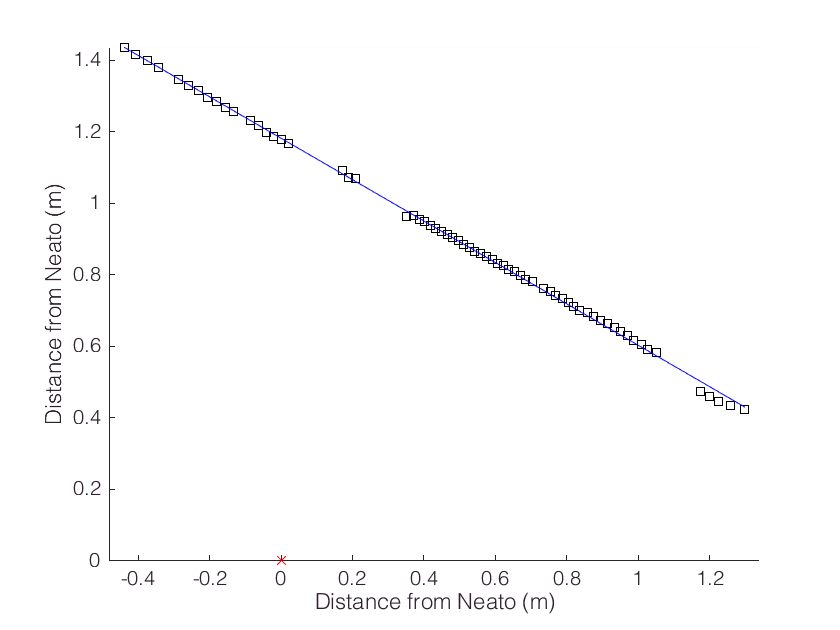

clean_data_calc_beta(r, theta, 1);

## Question 8

beta2 = 2×1 single column vector
   -2.3096
    0.6522


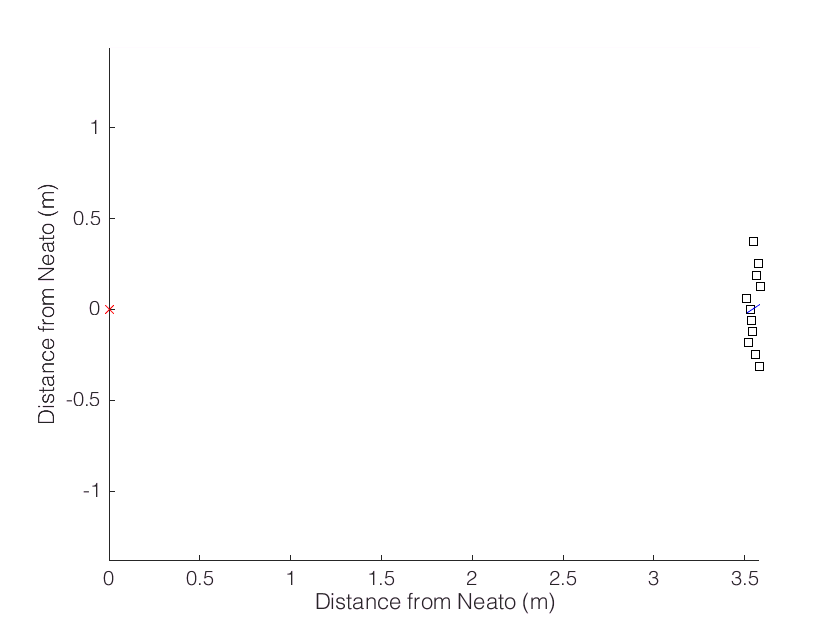

% Scan 2
load scan2
beta2 = clean_data_calc_beta(r, theta, 1)

beta3 = 2×1 single column vector
   -0.7406
   -0.0100


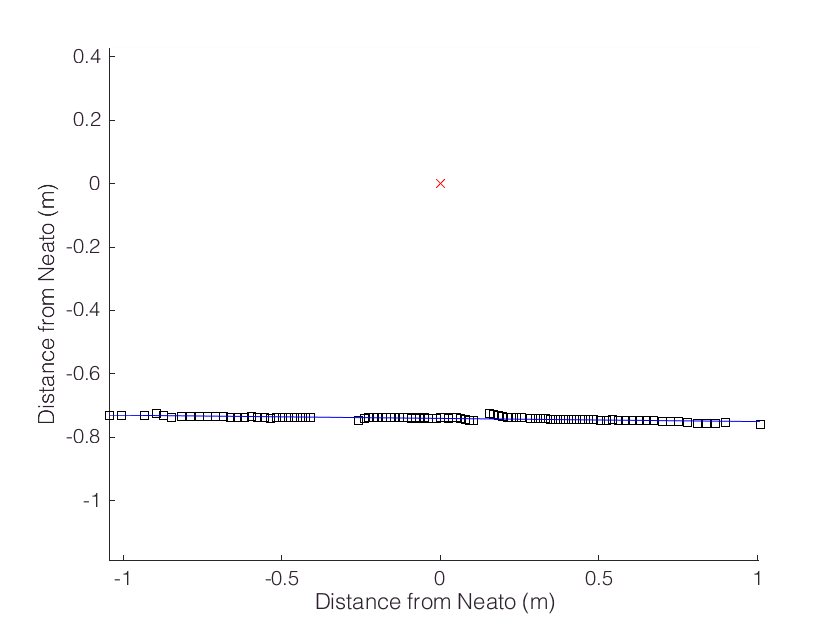

% Scan 3
load scan3
beta3 = clean_data_calc_beta(r, theta, 1)

beta4 = 2×1 single column vector
   -0.6050
    0.3067


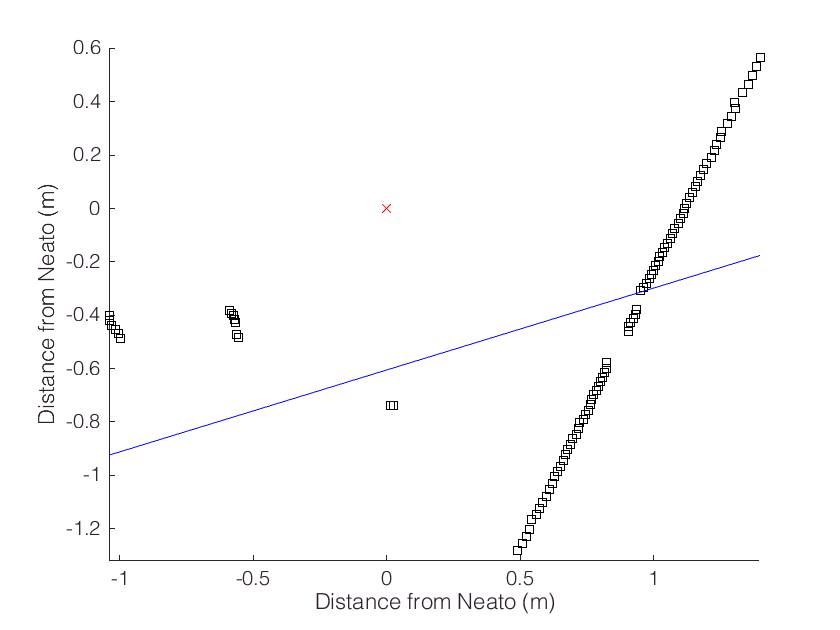

% Scan 4
load scan4
beta4 = clean_data_calc_beta(r, theta, 1)

## Question 9

In the first three cases, the line fitting appears to work well. However, when you have extra data points that do not lie on the line, as in scan 4, the points are going to throw off your calculation of *beta*. You need a way to remove those points prior to computing *beta*.

## Question 10

## Part A

This algorith should work because, by finding the first eigenvector (assuming our data is more or less linear), we can reorient (rotate) our axes so that the data varies most along the x-axis and least along the y-axis. Then we can use our old method of minimizing the squared vertical distance. To do this, we zero-mean the data (-shift), find *beta* to minimize the vertical squared distance, and add our shift (+shift) to the y-intercept component of *beta*. Then we can rotate our *beta* vector into our original reference frame. Having done this, we've effectively minimized the perpendicular distance between the points and the line.

## Part B

Find first eigenvector.

Find angle (*theta*) between first eigenvector and x-axis.

Rotate data about origin by *theta*.

Zero-mean data by subtracting *mean*.

Use linsolve to find the values of *beta*.

Shift *beta* by adding *mean* to its y-intercept component.

Rotate *beta* by *-theta*.

## Question 11

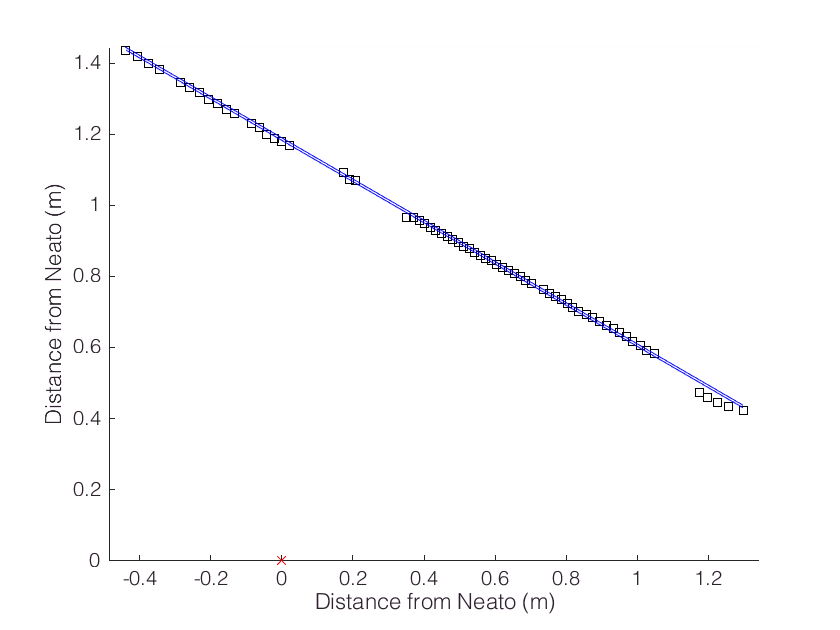

load scan1
clean_data_calc_beta_pca(r, theta, 1)

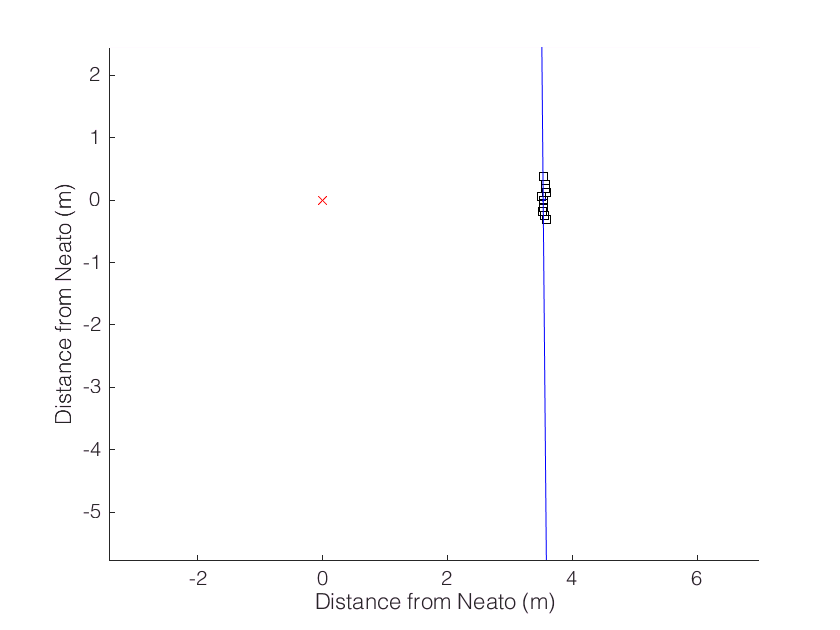

load scan2
clean_data_calc_beta_pca(r, theta, 1)

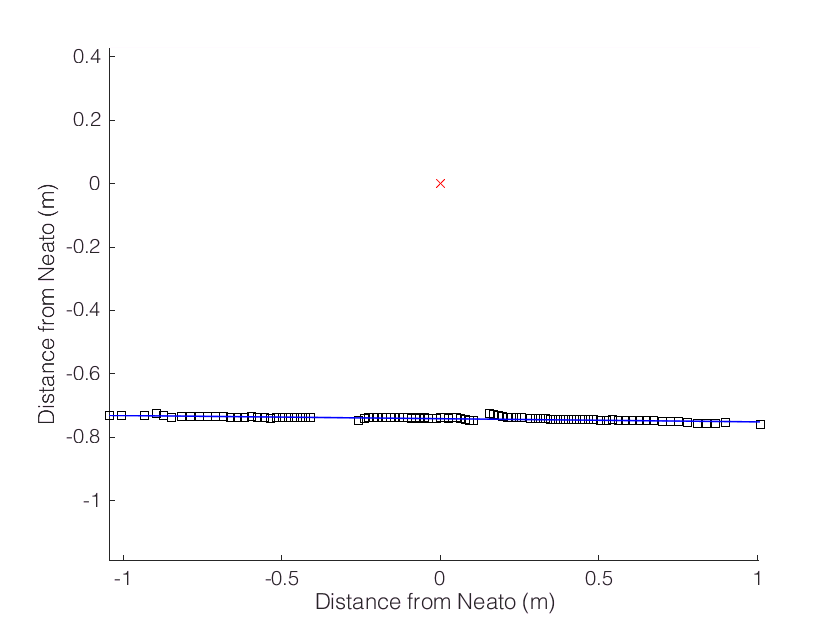

load scan3
clean_data_calc_beta_pca(r, theta, 1)

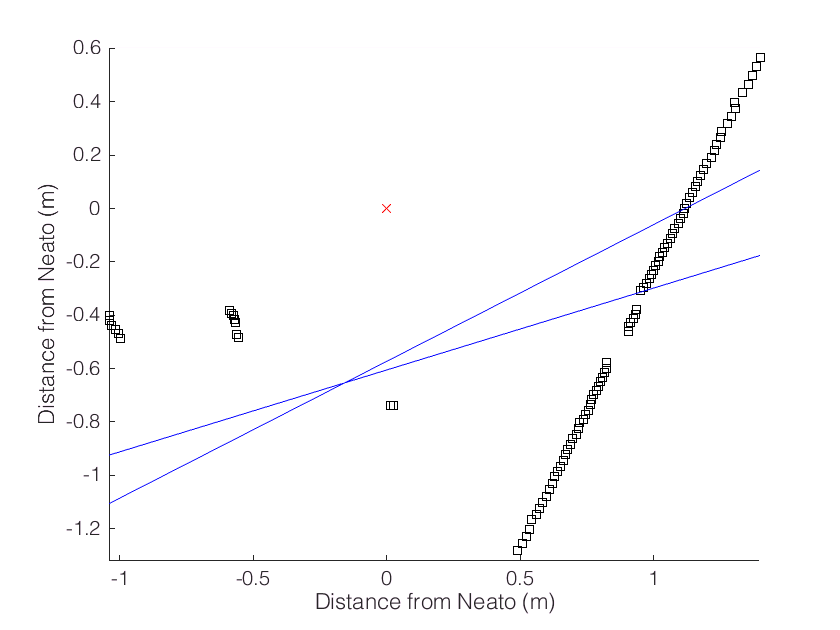

load scan4
clean_data_calc_beta_pca(r, theta, 1)

function beta = clean_data_calc_beta(r, theta, do_plot)
    % Remove data where r = 0
    [x, y] = clean_data(r, theta);
    % Calculate coefficient vector
    beta = calc_beta(x, y);
    % Plot the data, if desired
    if do_plot
        x_pred = [min(x) max(x)];
        y_pred = ([ones(size(x_pred,2),1) x_pred'] * beta)';
        figure;
        hold on;
        plot(0, 0, 'rx');
        plot(x, y, 'ks'); xlabel('Distance from Neato (m)'); ylabel('Distance from Neato (m)'); axis equal;
        plot(x_pred, y_pred, 'b');
        hold off;
    end
end
function [x, y] = clean_data(r, theta)
    % Remove data where r = 0
    theta_clean = theta(r~=0);
    r_clean = r(r~=0);
    x = r_clean.*cosd(theta_clean);
    y = r_clean.*sind(theta_clean);
end
function beta = calc_beta(x, y)
    X = [ones(size(x,1),1) x];
    beta = linsolve(X, y);
end
% From question 11
function beta = clean_data_calc_beta_pca(r, theta, do_plot)
    [x, y] = clean_data(r, theta);
    % Calculate coefficient vector using linsolve
    beta_lin = calc_beta(x, y);
    % Calculate coefficient vector using PCA
    V = pca([x y]);
    m = V(2,1)/V(2,2); % slope
    b = y(1) - m*x(1); % y-intercept
    beta_pca = [b m];
    % Plot the data, if desired
    if do_plot
        x_pred_lin = [min(x) max(x)];
        y_pred_lin = ([ones(size(x_pred_lin,2),1) x_pred_lin'] * beta_lin)';
        x_pred_pca = [min(x) max(x)];
        y_pred_pca = ([ones(size(x_pred_pca,2),1) x_pred_pca'] * beta_pca')';
        figure;
        hold on;
        plot(0, 0, 'rx');
        plot(x, y, 'ks'); xlabel('Distance from Neato (m)'); ylabel('Distance from Neato (m)'); axis equal;
        plot(x_pred_lin, y_pred_lin, 'b');
        plot(x_pred_pca, y_pred_pca, 'b');
        hold off;
    end
end